# Auto-generated by Image Acquisition Exp

# lorer

Generated in MATLAB R2022b on 23-Mar-2023 23:10:59

## Connect to Device

Create connection to the device using the specified adaptor with the specified format.

v = videoinput("winvideo", 1, "MJPG_1280x720");

## Configure Device Properties

Configure videoinput properties to prepare for acquisition.

v.ReturnedColorspace = "rgb";

## Capture Image

Capture a single frame.

image1 = getsnapshot(v);

% Set the desired file location and name.
filelocation = "C:\Users\56979\OneDrive - Universidad Técnica Federico Santa María (1)\ELO308";
filename = "snapshot1.png";
fullFilename = fullfile(filelocation, filename);

% Write image data to file.
imwrite(image1, fullFilename, "png");

## View Snapshot

Read from file and display the captured image.

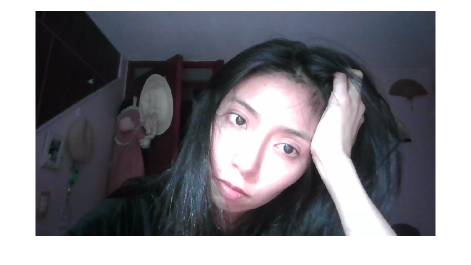

imageData = imread(fullFilename);
f = figure;
ax = axes(f);
imshow(imageData, "Parent", ax);

## Clean Up

Delete the videoinput object and clear variables from the workspace.

delete(v)
clear v